# tRGS Test

In this notebook, we're testing an implementation of tensor randomized Gauss Seidel.

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

l = 5;
p = 7;
n = 10;
m = 12;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

Now, let's test the implementation of tRGS.

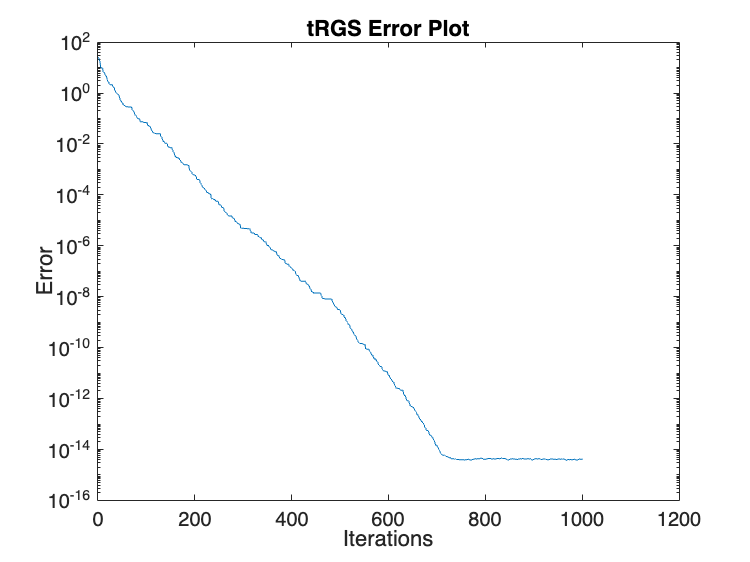

%run some iterations of tRK
num_its = 1000;
[~,its] = tRGS(A,B,randn(l,p,n),num_its);

%record errors
errs = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    errs = [errs,norm(est(:))];
end

%plot errors vs iterations
semilogy(errs)
hold on
title('tRGS Error Plot')
xlabel('Iterations') 
ylabel('Error') 

And it appears this implementation is working!